## Back to basics: Step 2.

## State model


$$x_{t+1} =x_t +v_t \cdot h+w_t$$



$$y=||r-r^{\left(i\right)} ||_2 \;+v_t$$



$$\mathit{\mathbf{x}}=\left\lbrack \begin{array}{c}
x\\
v_x 
\end{array}\right\rbrack$$
    
$$A=\left\lbrack \begin{array}{cc}
1 & h\\
0 & 1
\end{array}\right\rbrack$$



$$x_{t+1} ={Ax}_t +w_t$$



$$y_t =h\left(x_t ,v_t \right)$$


The model dynamics are linear, the output is not.

1 - dimensional travel random walk. Position and velocity as the states of the system.

This is very similar to the example in `5_ekf.ipynb`

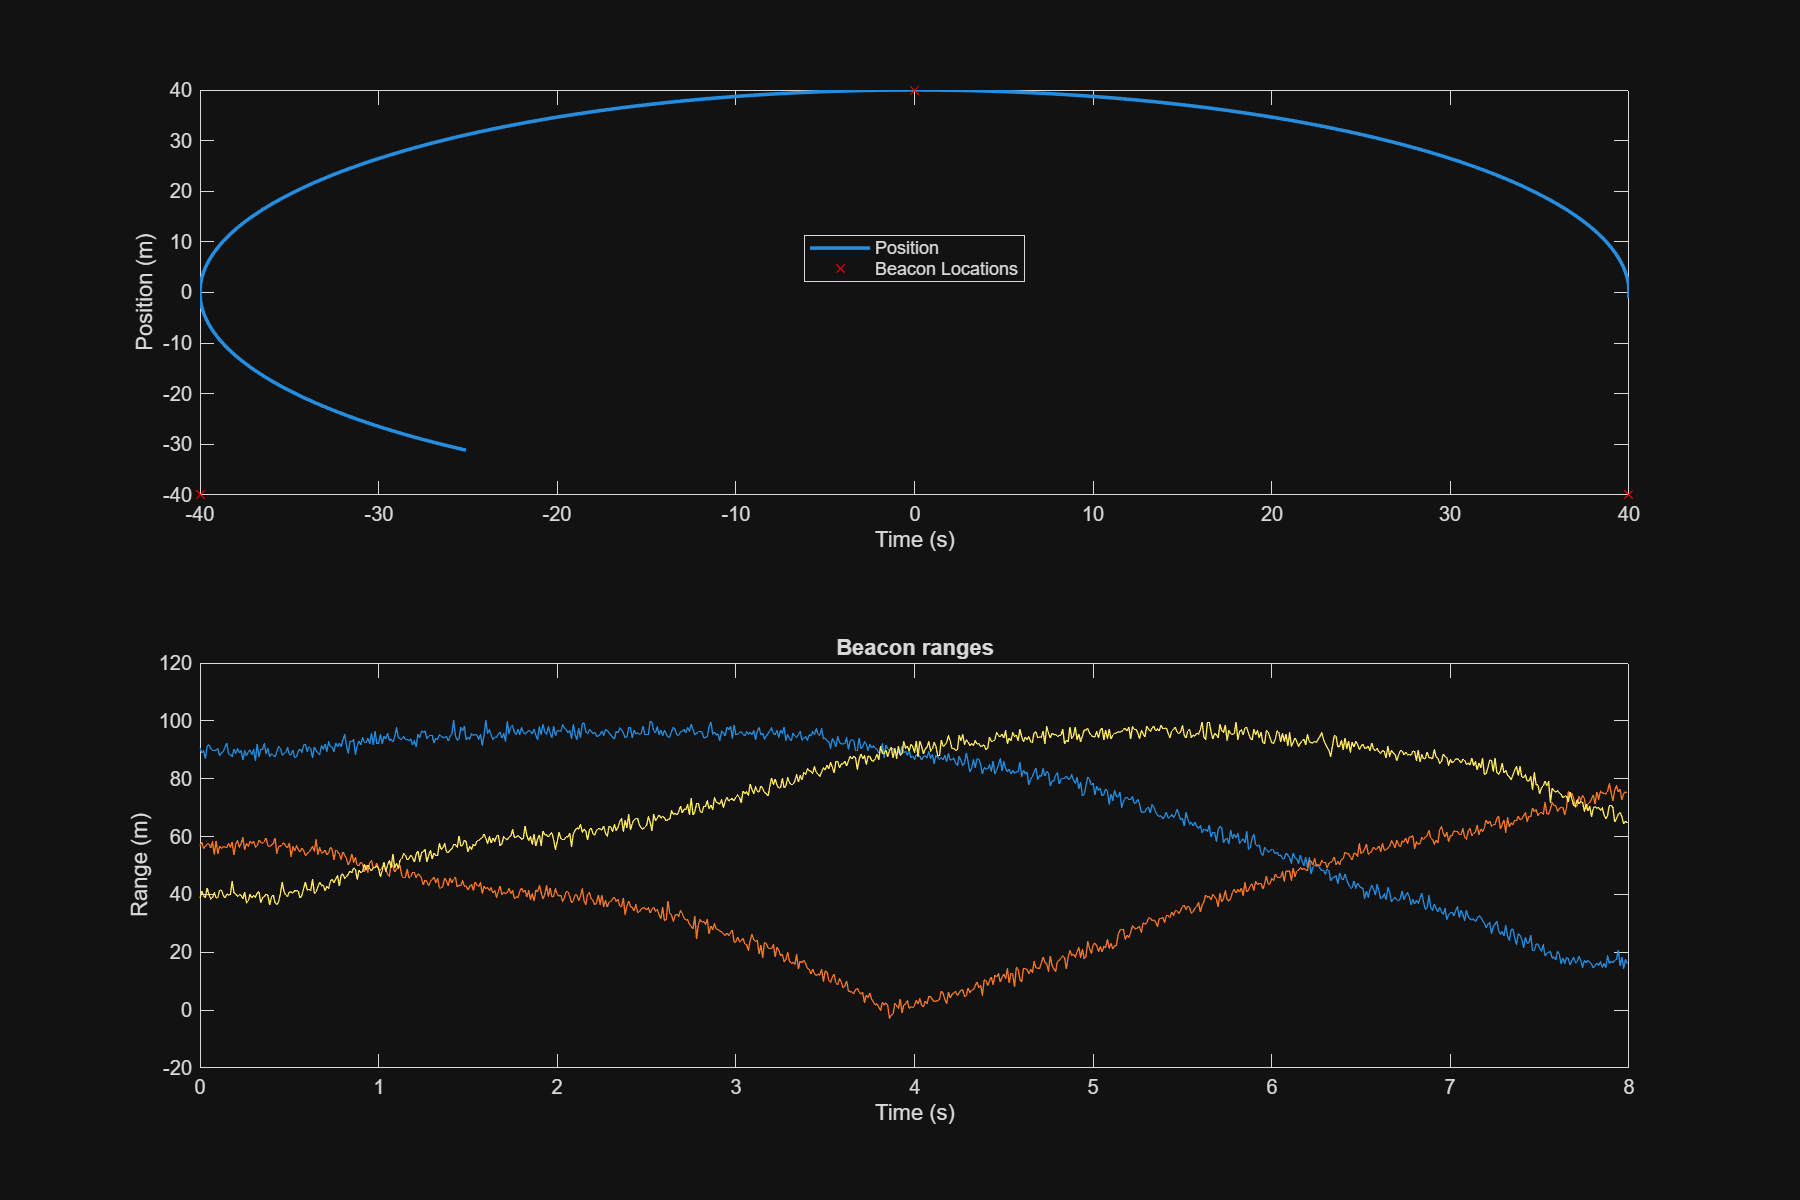

% Make sure to add Casadi to path and import it.
import casadi.*

% Setup.
fs = 100;
ht = 1/fs;

% State transition matrix.
A = [1 ht;
     0 1];

% Noise variance for velocity, no position variance.
v_std = 1.5;
Q = [0 0;
     0 v_std^2];

% Define where the beacons are on the track. These are triangular around
% the track. If we change the locations, this will provide worse estimates.
beaconLocations = [-45 0 45; -45 45 -45]';
nBeacons = length(beaconLocations);

% Track size.
trackRadius = 40;

% Jacobian set up.
% Variable.
x = MX.sym('x', 2);

% Arc positiion.
s = x(1);

% Map arc-length position to cartesian co-ordinates.
px = trackRadius * cos(s / trackRadius);
py = trackRadius * sin(s / trackRadius);

% Range to each beacon, loop over the function for each beacon.
h = MX.zeros(nBeacons, 1);
for i = 1 : nBeacons
    h(i) = sqrt((px - beaconLocations(i, 1)) ^ 2 + (py - beaconLocations(i, 2)) ^ 2);
end

% Jacobian here.
jh = jacobian(h, x);
Jhx = Function('h', {x}, {h});
Jh = Function('Jh', {x}, {jh});

% Measurement noise.
mu = zeros(1, nBeacons);
r = 1.5;
R = r^2 * eye(nBeacons);

% Initialisation.
nSamples = 800;
timeVector = (0 : nSamples) * ht;
stateVector = zeros(2, nSamples + 1);

% Need x and y co-ordinates.
measurementVector = zeros(nBeacons, nSamples);
currentPositionTrackX = zeros(1, nSamples);
currentPositionTrackY = zeros(1, nSamples);

% Initialisation
stateVector(:, 1) = [0 0]';

for t = 1 : nSamples

    % Noise for the velocity.
    processNoise = mvnrnd([0 0], Q)';

    % Note that there's no input terms here. They're in the script for
    % testing, but omitted because the model doesn't call for it.
    stateVector(:, t + 1) = A * stateVector(:, t) + processNoise;

    currentPositionTrackX(:, t) = trackRadius * cos(stateVector(1, t) / trackRadius);
    currentPositionTrackY(:, t) = trackRadius * sin(stateVector(1, t) / trackRadius);
    trackPosition = [currentPositionTrackX(:, t) currentPositionTrackY(:, t)];

    % Euclidean distance of the current position to each beacon location.
    distFromBeacons = vecnorm(trackPosition - beaconLocations, 2, 2);

    % Actual noise model provided.
    measurementNoise = mvnrnd(mu, R)';

    % Final measurement.
    measurementVector(:, t) =  distFromBeacons + measurementNoise;

end

f = figure;
f.Position = [0 0 1200 800];
tiledlayout(2, 1)
nexttile
plot(currentPositionTrackX, currentPositionTrackY, 'LineWidth', 1.8, 'DisplayName', 'Position')
hold on
scatter(beaconLocations(:, 1), beaconLocations(:, 2), 'rx', 'DisplayName', 'Beacon Locations')
xlabel('Time (s)')
ylabel('Position (m)')
legend('Location', 'best')

nexttile
grid on;
plot(timeVector(1 : end - 1), measurementVector)
xlabel('Time (s)'); ylabel('Range (m)'); title('Beacon ranges')

This makes sense, the object travels towards each beacon location, (displacement is approximately 0 at this point relative to the beacon), then travels away.

Note: Because the velocity is not driven and is unconstrained in this example, it may take a few runs before you get the desired behaviour. 

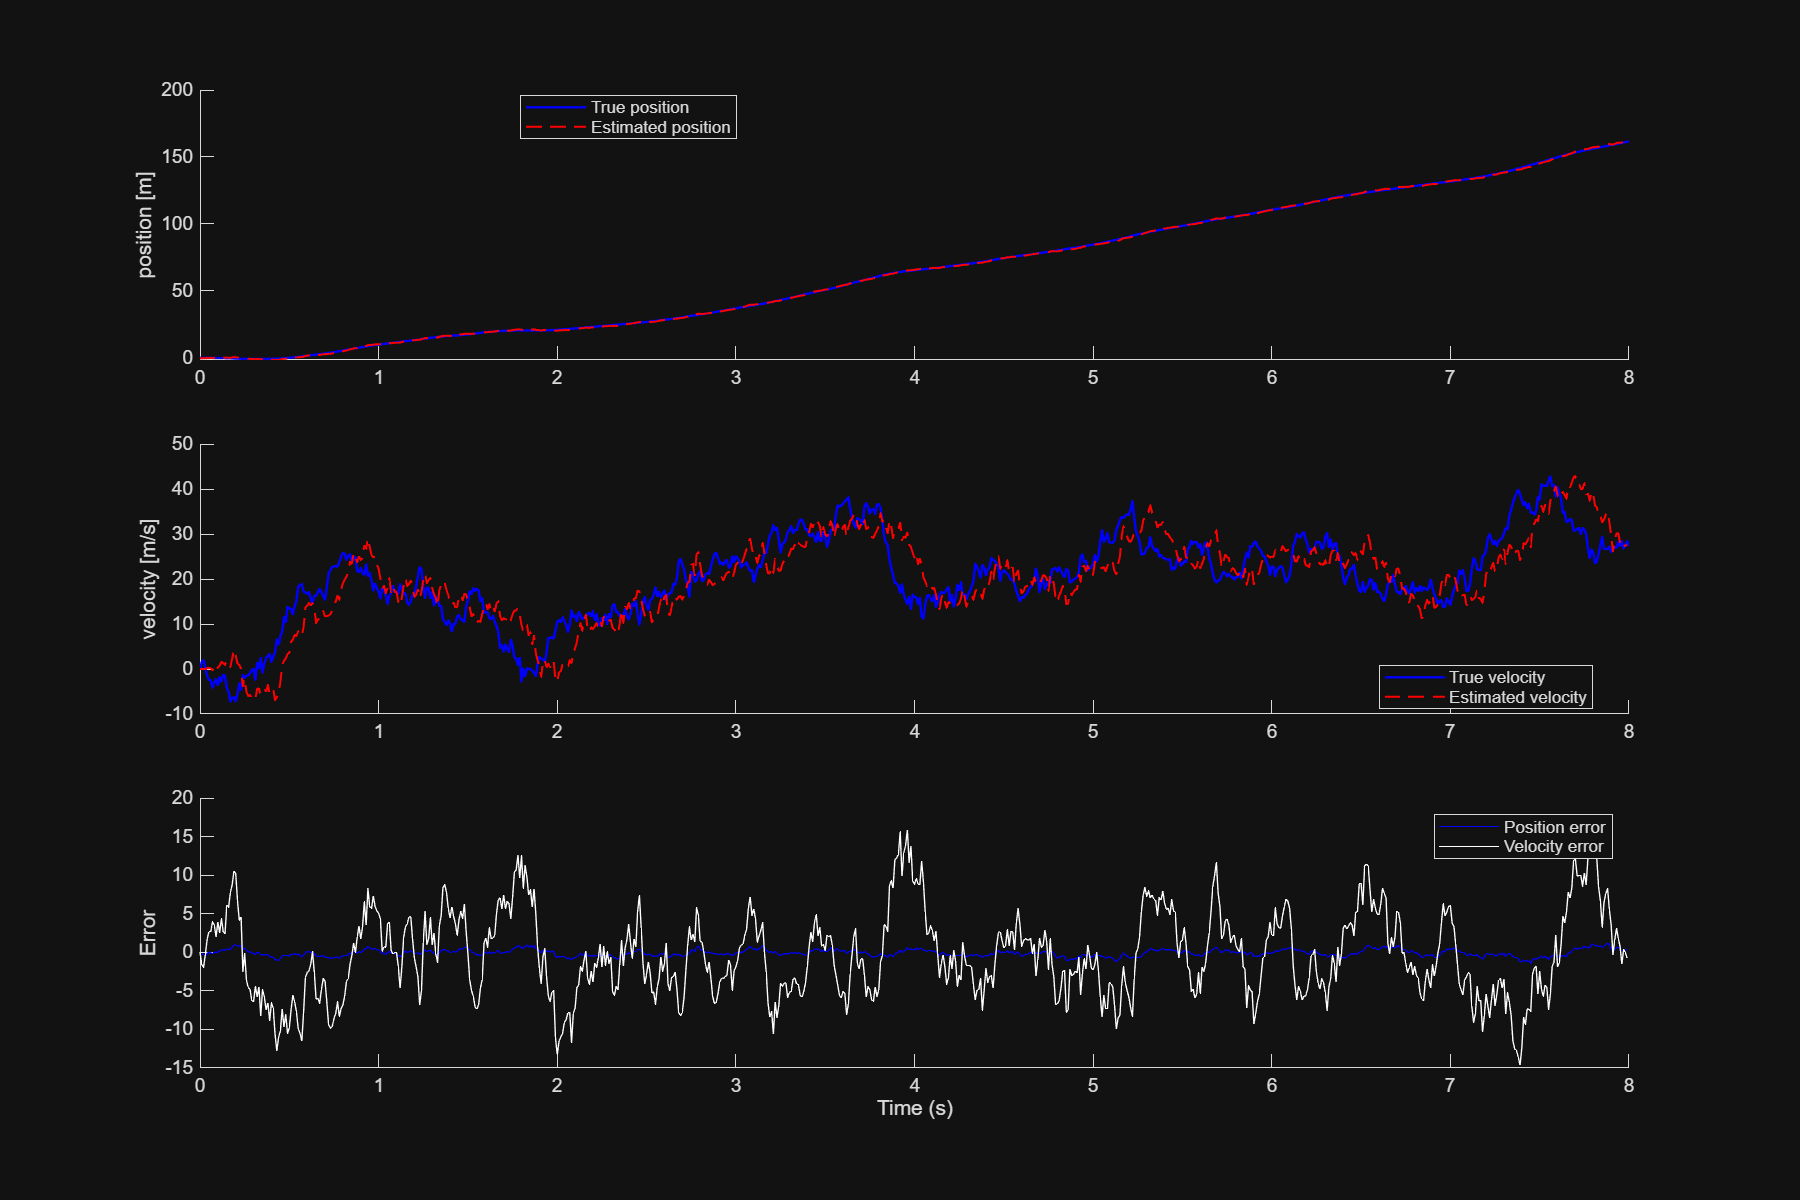

% Initialise these.
x_mu = zeros(2, nSamples);
sigma_mu = cell(1, nSamples);

% Initial estimate. Needs to be small for convergence.
x_tu = [0; 0];
sigma_tu = diag([10, 5]);

for k = 1 : nSamples
    % Jacobian steps to compute before Kalman Filter.
    h_x = full(Jhx(x_tu));
    C_lin = full(Jh(x_tu));
 
    % Keep a log of sigma and the estimated state. Measurement update.
    [sigma_mu{:, k}, x_mu(:, k)] = measurementUpdate(sigma_tu, x_tu, ...
        measurementVector(:, k), C_lin, R, h_x);

    % Time update step.
    [sigma_tu, x_tu] = timeUpdate(sigma_mu{:, k}, x_mu(:, k), A, Q);

end

f = figure;
f.Position = [0 0 1200 800];
tiledlayout(3, 1)

% Plots.
nexttile
hold on;
plot(timeVector, stateVector(1,:), 'b', 'LineWidth', 1.2, 'DisplayName', 'True position')
plot(timeVector(1 : end - 1), x_mu(1,:), 'r--', 'LineWidth', 1, 'DisplayName', 'Estimated position')
ylabel('position [m]');
legend('Location','best')

nexttile
hold on;
plot(timeVector, stateVector(2,:), 'b', 'LineWidth', 1.2, 'DisplayName', 'True velocity')
plot(timeVector(1 : end - 1), x_mu(2,:), 'r--', 'LineWidth', 1, 'DisplayName', 'Estimated velocity')
ylabel('velocity [m/s]')
legend('Location','best')

nexttile
hold on
positionError = x_mu(1,:) - stateVector(1,1 : end - 1);
velocityError = x_mu(2,:) - stateVector(2,1 : end - 1);
plot(timeVector(1 : end - 1), positionError, 'b', 'DisplayName', 'Position error')
plot(timeVector(1 : end - 1), velocityError, 'w', 'DisplayName', 'Velocity error')
ylabel('Error')
xlabel('Time (s)')
legend

Position estimation is so good here because we have 3 beacons. If we take out one of the beacons, it becomes worse. If we only have 1 beacon, the estimator doesn't know which side the beacon is on.

Bare in mind this is only in one dimension, if we bump it up to 2 dimensions, the effect will be exacerbated due to circumferential geometry.

function [sigma, x] = measurementUpdate(sigma, x, y, C, R, h_x)
    z = C * sigma * C' + R;
    x = x + sigma * C' * linsolve(z, y - h_x);
    sigma = sigma - sigma * C' * linsolve(z, C * sigma);
end

function [sigma, x] = timeUpdate(sigma, x, A, Q)
    x = A * x;
    sigma = A * sigma * A' + Q;
end